%1
tools = few256;
dxtools = conv2(tools, deltax('conv2'), 'valid');
dytools = conv2(tools, deltay('conv2'), 'valid');

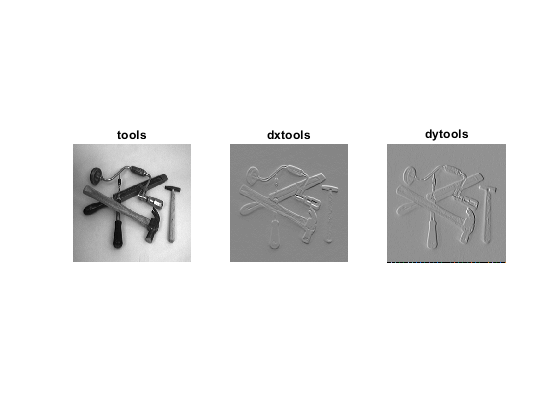

figure(1)
subplot(1,3,1)
showgrey(tools)
title('tools')
subplot(1,3,2)
showgrey(dxtools)
title('dxtools')
subplot(1,3,3)
showgrey(dytools)
title('dytools')

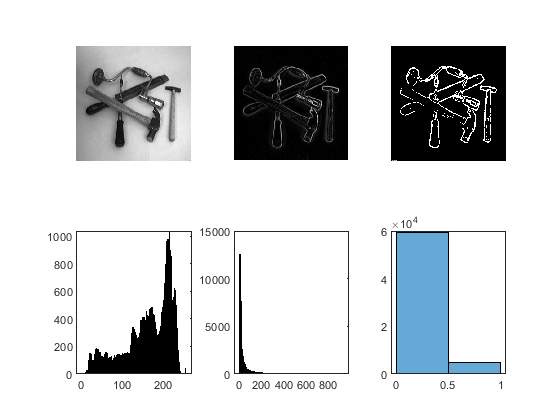

%2 
gradmagntools = sqrt(dxtools .^2 + dytools .^2);
threshold = 150;

figure(2)
subplot(2,3,1)
showgrey(tools);
subplot(2,3,2)
showgrey(gradmagntools);
subplot(2,3,3)
showgrey((gradmagntools - threshold) > 0);
subplot(2,3,4)
histogram(tools,255);
subplot(2,3,5)
histogram(gradmagntools);
subplot(2,3,6)
histogram((gradmagntools - threshold) > 0,2);

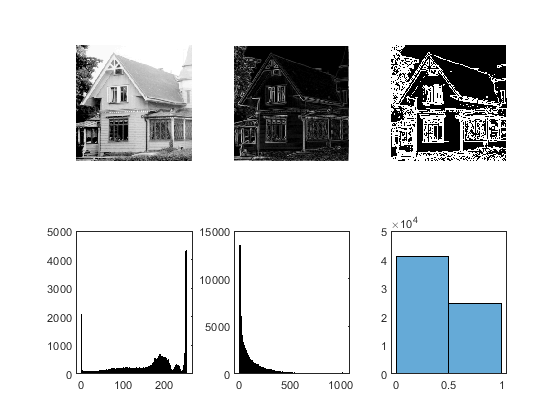

%2
godthem = godthem256;
% no smoothing
gradmagngod = Lv(godthem, 0, 'same');
t = 100;

figure(3)
subplot(2,3,1)
showgrey(godthem);
subplot(2,3,2)
showgrey(gradmagngod);
subplot(2,3,3)
showgrey((gradmagngod - t) > 0);
subplot(2,3,4)
histogram(godthem,255);
subplot(2,3,5)
histogram(gradmagngod);
subplot(2,3,6)
histogram((gradmagngod - t) > 0,2);

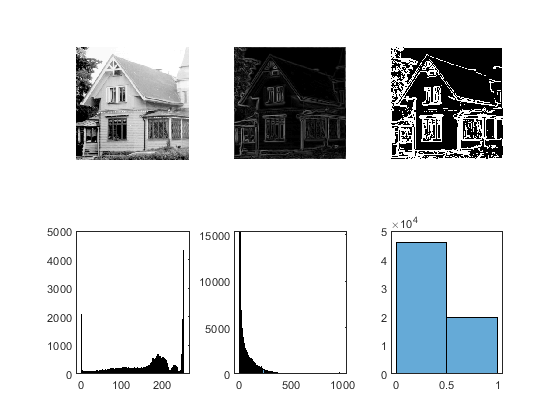

%3
% smoothing
gradmagngod_smooth = Lv(godthem,1, 'same');

figure(4)
subplot(2,3,1)
showgrey(godthem);
subplot(2,3,2)
showgrey(gradmagngod_smooth);
subplot(2,3,3)
showgrey((gradmagngod_smooth - t) > 0);
subplot(2,3,4)
histogram(godthem,255);
subplot(2,3,5)
histogram(gradmagngod_smooth);
subplot(2,3,6)
histogram((gradmagngod_smooth - t) > 0,2);

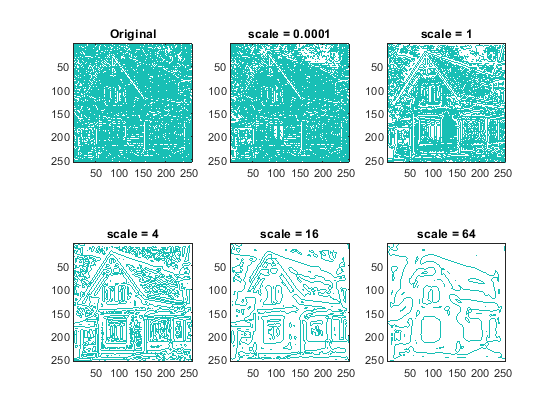

%4
house = godthem256;
scale = [0.0001 1.0  4.0 16.0 64.0];
figure(5)
subplot(2,3,1)
contour(Lvvtilde(house, 0, 'same'), [0 0])
axis('image')
axis('ij')
title('Original')
for i=1:length(scale)
    subplot(2,3,i+1)
    contour(Lvvtilde(house, scale(i), 'same'), [0 0])
    axis('image')
    axis('ij')
    title(['scale = ' num2str(scale(i))])
end

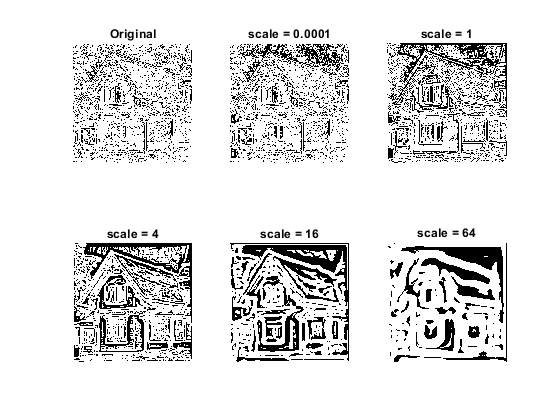

house = godthem256;
scale = [0.0001 1.0  4.0 16.0 64.0];
figure(6)
subplot(2,3,1)
showgrey(Lvvvtilde(house, 0, 'same') < 0)
axis('image')
axis('ij')
title('Original')
for i=1:length(scale)
    subplot(2,3,i+1)
    showgrey(Lvvvtilde(house, scale(i), 'same') < 0)
    axis('image')
    axis('ij')
    title(['scale = ' num2str(scale(i))])
end

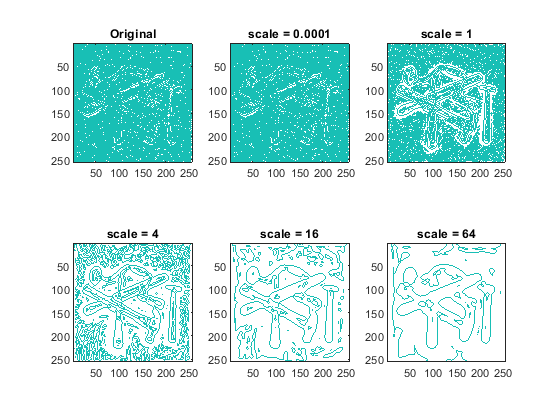

tools = few256;
figure(7)
subplot(2,3,1)
contour(Lvvtilde(tools, 0, 'same'), [0 0])
axis('image')
axis('ij')
title('Original')
for j=1:length(scale)
    subplot(2,3,j+1)
    contour(Lvvtilde(tools, scale(j), 'same'), [0 0])
    axis('image')
    axis('ij')
    title(['scale = ' num2str(scale(j))])
end

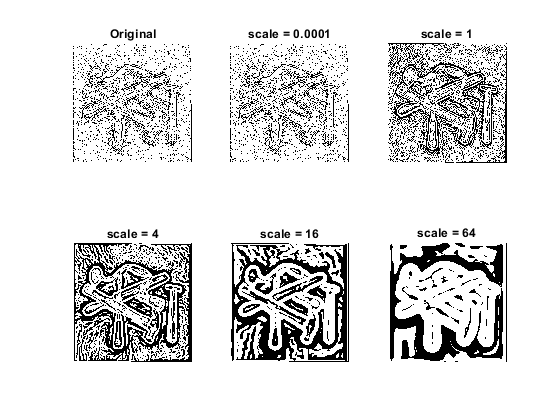

%5
tools = few256;
figure(8)
subplot(2,3,1)
showgrey(Lvvvtilde(tools, 0, 'same') < 0)
axis('image')
axis('ij')
title('Original')
for j=1:length(scale)
    subplot(2,3,j+1)
    showgrey(Lvvvtilde(tools, scale(j), 'same') < 0)
    axis('image')
    axis('ij')
    title(['scale = ' num2str(scale(j))])
end

%7 
figure(9)
subplot(1,2,1)
image = godthem256;
curves = extractedge(image, 2, 50);

overlaycurves(image, curves);

subplot(1,2,2)
image = few256;
curves = extractedge(image, 8, 40);

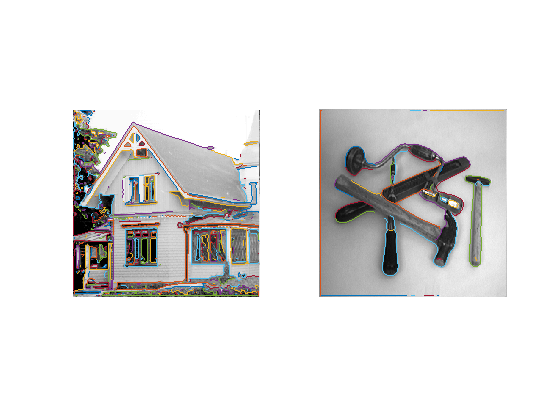

overlaycurves(image, curves);

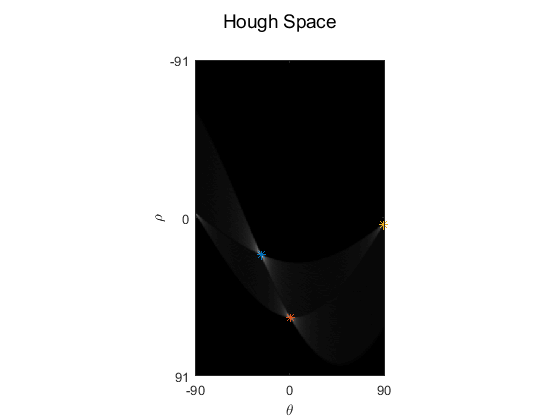

%8
pic = triangle128;
[linepar acc] = houghedgeline(pic, 0.5, 40, ...
    500, 300, 3, 0.1, 1, 2);

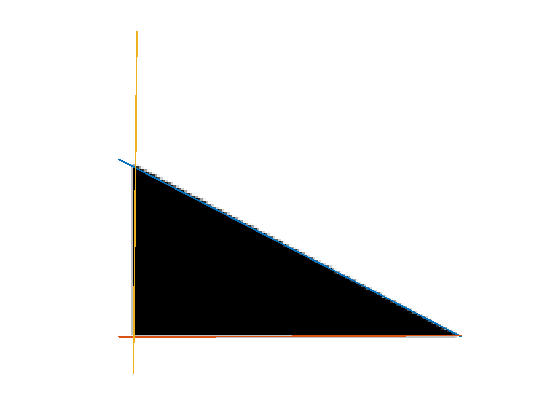

figure(11)
plot_line(pic,linepar)

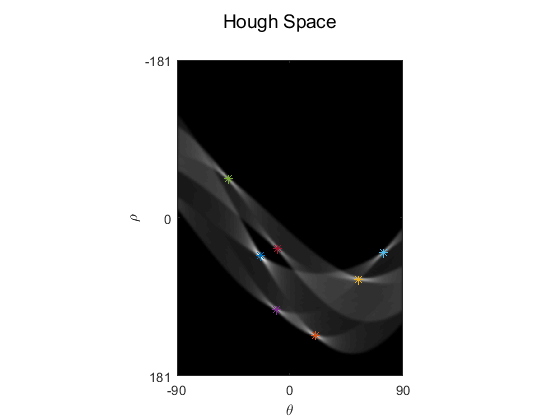

pic = houghtest256;
[linepar acc] = houghedgeline(pic, 0.5, 60, ...
    700, 500, 7, 0.7, 1, 2);

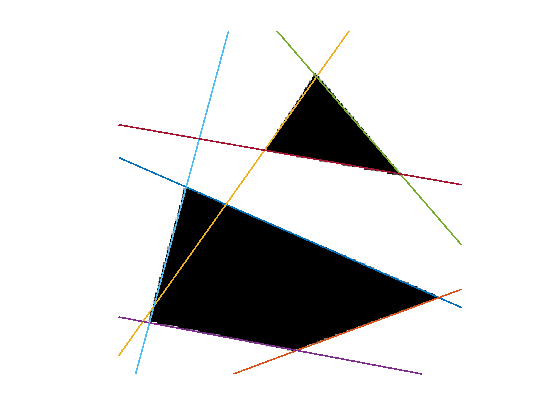

figure(12)
plot_line(pic,linepar)

figure(13)

pic = few256;
[linepar acc] = houghedgeline(pic, 1, 100, ...
    1000, 50, 12, 0, 0, 0);

subplot(1,3,1)
plot_line(pic,linepar)

pic = phonecalc256;
[linepar acc] = houghedgeline(pic, 8, 50, ...
    1000, 50, 7, 0, 1, 0);

subplot(1,3,2)
plot_line(pic,linepar)

pic = godthem256;
[linepar acc] = houghedgeline(pic, 5, 40, ...
    1000, 50, 15, 0, 0, 0);

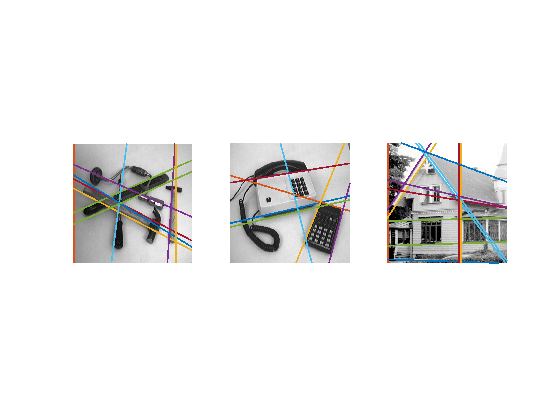

subplot(1,3,3)
plot_line(pic,linepar)